    LiveScript:

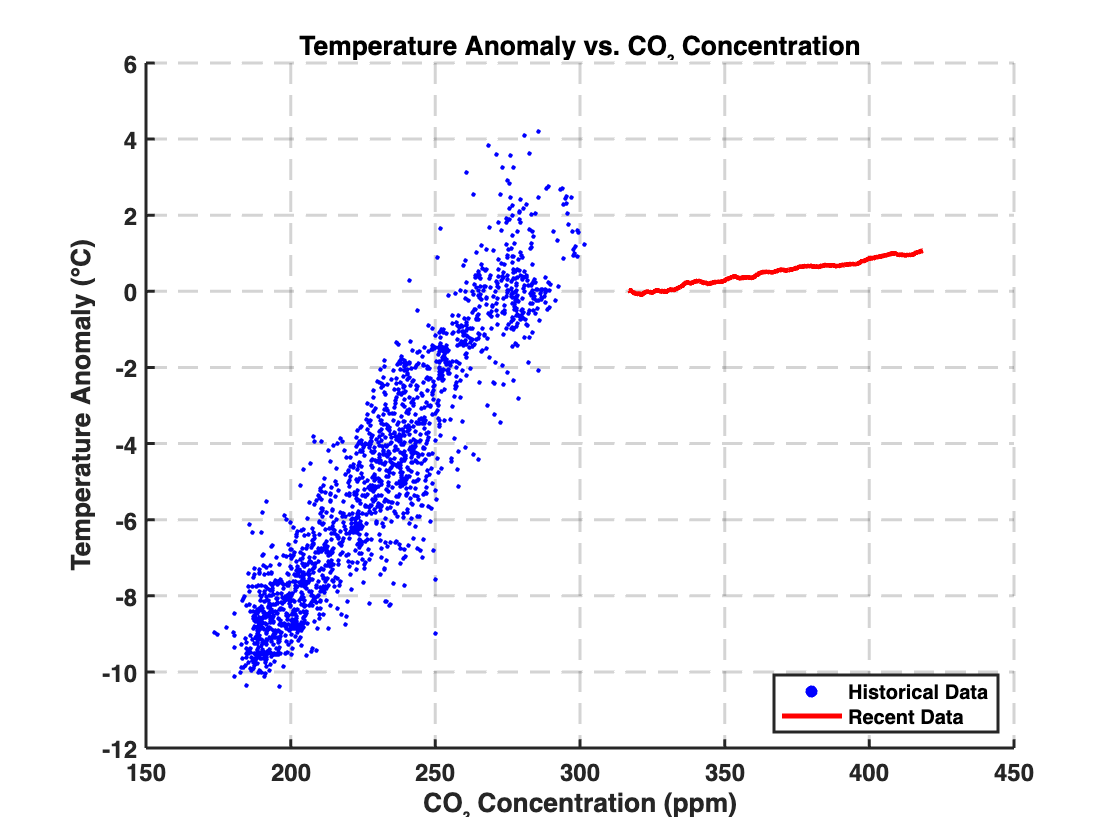

% Call the functions with the specified filename
[iceCO2Years, iceCO2] = readIceCoreCO2Data('antarctica2015co2composite.txt');
[iceTempYears, iceTemp] = readIceCoreTempData('EPICA Dome C Ice Core 800KYr Deuter.txt');
[recentTempYears, recentTemp] = readRecentTempData('Land_and_Ocean_complete.txt');
[recentCO2Years, recentCO2] = readRecentCO2Data('co2_mm_mlo.csv');


% Step 5: Align historical CO₂ and temperature anomaly data by interpolation

% Determine the range of the temperature data
minTempYear = min(iceTempYears);
maxTempYear = max(iceTempYears);

% Restrict CO₂ data to the range of temperature data
validIndices = (iceCO2Years >= minTempYear) & (iceCO2Years <= maxTempYear);
alignedCO2Years = iceCO2Years(validIndices);
alignedCO2 = iceCO2(validIndices);

% Interpolate temperature anomalies at the CO₂ data points
alignedTemp = interp1(iceTempYears, iceTemp, alignedCO2Years, 'linear');

% Step 5B: Align recent CO₂ and temperature anomaly data with smoothing

% Ensure temperature data aligns with CO₂ data
validTempIndices = recentTempYears >= 1958.16;
filteredTempYears = recentTempYears(validTempIndices);
filteredTemp = recentTemp(validTempIndices);

% Apply 5-year (60-month) centered moving average
windowSize = 60;
smoothedCO2 = movmean(recentCO2, windowSize, 'Endpoints', 'discard');
smoothedTemp = movmean(filteredTemp, windowSize, 'Endpoints', 'discard');

% Align years after smoothing
alignedYears = filteredTempYears(ceil(windowSize/2):end-floor(windowSize/2));

% Step 6: Plot historical data
figure;
scatter(alignedCO2, alignedTemp, 5, 'b', 'filled'); % Use size 10 for smaller blue dots
hold on;

% Step 7: Plot recent data on the same axes
plot(smoothedCO2, smoothedTemp, 'r-', 'LineWidth', 2.5); % Increase line thickness to 2.5

% Step 8: Customize the plot
xlabel('CO₂ Concentration (ppm)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Temperature Anomaly (°C)', 'FontSize', 14, 'FontWeight', 'bold');
title('Temperature Anomaly vs. CO₂ Concentration', 'FontSize', 16, 'FontWeight', 'bold');
legend('Historical Data', 'Recent Data', 'FontSize', 10, 'Location', 'SouthEast');
grid on;

% Customize grid and axes
ax = gca; % Get current axes
ax.GridLineStyle = '--'; % Dashed gridlines
ax.GridAlpha = 0.2; % Semi-transparent gridlines
ax.LineWidth = 1.5; % Thicker gridlines and axes lines
ax.FontSize = 12; % Increase font size for tick labels
ax.FontWeight = 'bold'; % Bold tick labels

hold off;

Helper Functions:

% Helper Functions
function [years, co2] = readRecentCO2Data(filename)
    % Open the file
    fid = fopen(filename, 'r');
    if fid == -1
        error('Cannot open file: %s', filename);
    end
    
    % Initialize variables
    data = [];
    
    while ~feof(fid)
        line = fgetl(fid);
        if ischar(line)
            % Attempt to convert the line to numeric values
            numericData = str2num(line); %#ok<ST2NM>
            if ~isempty(numericData) && numel(numericData) >= 4
                % Append the correct columns to the data array
                data = [data; numericData([1 2 4])];
            end
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Separate the data into years and co2
    years = data(:, 1)' + (data(:,2)-1)'/12;
    co2 = data(:, 3)';
end

function [years, temp] = readRecentTempData(filename)
    % Open the file
    fid = fopen(filename, 'r');
    if fid == -1
        error('Cannot open file: %s', filename);
    end
    
    % Initialize variables
    data = [];
    
    % Read through the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if ischar(line)
            % Attempt to convert the line to numeric values
            numericData = str2num(line); %#ok<ST2NM>
            if ~isempty(numericData) && numel(numericData) >= 12
                % Append the correct columns to the data array
                data = [data; numericData(1:3)];
            end
        end
        % the file has the data twice; we quit after readin the first batch
        if size(data,1) > 2 && isempty(numericData)
            break;
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Separate the data into years and co2
    years = data(:, 1)' + (data(:,2)'-1)/12;
    temp = data(:, 3)';

end

function [years, temp] = readIceCoreTempData(filename)
    % Open the file
    fid = fopen(filename, 'r');
    if fid == -1
        error('Cannot open file: %s', filename);
    end
    
    % Initialize variables
    data = [];
      
    % Read through the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if ischar(line)
            % Attempt to convert the line to numeric values
            numericData = str2num(line); %#ok<ST2NM>
            if ~isempty(numericData) && numel(numericData) >= 5
                % Append the correct columns to the data array
                data = [data; numericData(3) numericData(5)];
            end
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Separate the data into years and co2
    yearsBP = data(:, 1)';
    temp = data(:, 2)';
    
    % Convert years BP to calendar years (AD/BC)
    years = 1950 - yearsBP;
    
    % Flip the vectors to have the oldest years first
    years = flip(years);
    temp = flip(temp);
end

function [years, co2] = readIceCoreCO2Data(filename)
    % Open the file for reading
    fid = fopen(filename, 'r');
    if fid == -1
        error('Cannot open file: %s', filename);
    end

    % Initialize cell arrays to store data
    yearsBP = {};
    co2 = {};

    % Read the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if ischar(line)
            % Attempt to convert the line to numeric values
            numericData = str2num(line); %#ok<ST2NM>
            if ~isempty(numericData) && numel(numericData) >= 2
                % Store the first two numeric values
                yearsBP{end+1} = numericData(1); %#ok<AGROW>
                co2{end+1} = numericData(2); %#ok<AGROW>
            end
        end
    end

    % Close the file
    fclose(fid);

    % Convert cell arrays to numeric vectors
    yearsBP = cell2mat(yearsBP);
    co2 = cell2mat(co2);

    % Convert years before 1950 to Gregorian calendar years
    years = 1950 - yearsBP;

    % Flip the vectors to have the oldest data first
    years = flip(years);
    co2 = flip(co2);
end




